# Analysis of local tuning biases in the mouse dLGN

- link abstract or complete manuscript/thesis

TO DO

- finalize rank sum? perhaps not because it would require adding description of binarization process whackkk

- add discussion and some references

- convert to mark down

## Overview

The aim of the project is to assess the presence of 'local tuning biases' among populations of LGN afferents innervating the mouse V1. From a computer vision point of view, we test the notion that neurons/units in the dLGN 'process' image regions with a similar, or biased, set of orientated filters. 

To answer this question. We need to estimate the spatial receptive fields and feature tuning of populations of thalamic boutons innervating mouse V1. Then, for each pair of boutons, we determine the extent to which their receptive fields overlap and the similarity of their tuning profiles

If LGN boutons with overlapping receptive fields have similar tuning profiles, this would suggest the presence of local tuning biases.

# Methods

## Data collection 

First we measure the visual properties of mouse V1 boutons using resonant, two-photon microscopy in the awake, behaving mouse. A total of three mice were used in this study. We imaged [N} unique cortical fields to obtain the data discussed here.

## Kernel Estimation

A bouton’s joint tuning to orientation and spatial frequency is measured by presenting a sequence of flashed, high-contrast sinusoidal gratings having pseudorandom orientations and spatial frequencies [FIGURE]. We estimated the tuning of each bouton by linearly regressing its response on the grating stimulus and denote the estimated tuning kernel of the ith bouton in an imaging field. The peak of the tuning kernel also yielded a spatial frequency preference and an orientation preference for each bouton [FIGURE]

We also measured the spatial receptive field maps of boutons by presenting a sequence of flickering, elongated bars at random orientations and positions across the visual field [FIGURE]. A boutons RF map was estimated by correlating its response and the location of the bars. 

## Image Processing

After imaging a field, we manually segmented **regions of interest  (ROIS) **which corresponded micrometer-sized circular or elliptical boutons of dLGN axons. Then for each ROI we extracted signals by computing the mean of the calcium fluorescence within each region of interest and discounting the signals from the nearby neuropil. Spikes were then estimated via deconvolution.

# Loading Data Table Containing Properties of Boutons/ROIs

To begin the the analysis, we first get the tuning kernels and receptive fields of thalamic boutons. To do this we load the ROI data table. This section shows how to load this table. 

Rows of the table correspond to some lgn bouton in some imaging field and columns correspond some property of that bouton. *Here are some of these properties...*

tuning properties

- kern_tun is the tuning kernel of bouton, which represents its response to the joint spatial frequency and orientation of a grating

- oriest is the orientation preference of the bouton/roi

- osi is the orientation selectivity of the bouton

- sfPeak is the peak spatial frequency preferences of the bouton

- signifi_tun represesents whethere or not (1 or 0) the boutons's tuning kernel is  'significant'. That is, some boutons have tuning kernels are too noisy. only play with those that are clean and crisp.

properties of the bouton's receptive fields

- kern_ret is the spatial receptive field map/kernel of the bouton, which represents its response to different regions of visual space

- signifi_ret represesents whethere or not (1 or 0) the boutons's spatial receptive field imap/kernel os  'significant'. That is, some boutons have receptive fields maps that are too noisy. Only play with those that are clean and crisp. 

`Note that this analysis only considers boutons that have significant tuning kernels and receptive field maps.`

## *Getting the Table...*

% INITIALIZE CLASS
clear;
clc;
addpath /Users/luis/Box/prjLGNTB/lgnDATA/   
addpath /Users/luis/Box/prjLGNTB/lgnANALYSIS/
cd /Users/luis/Box/prjLGNTB/lgnANALYSIS
lgn = lgnanz;

Select your imaging fields of boutons  (there are 9 total)

% lgn.all_available_uif'
uifs_to_process = lgn.all_available_uif()

uifs_to_process =      1
     2
     3
     9


Generate the roi table.

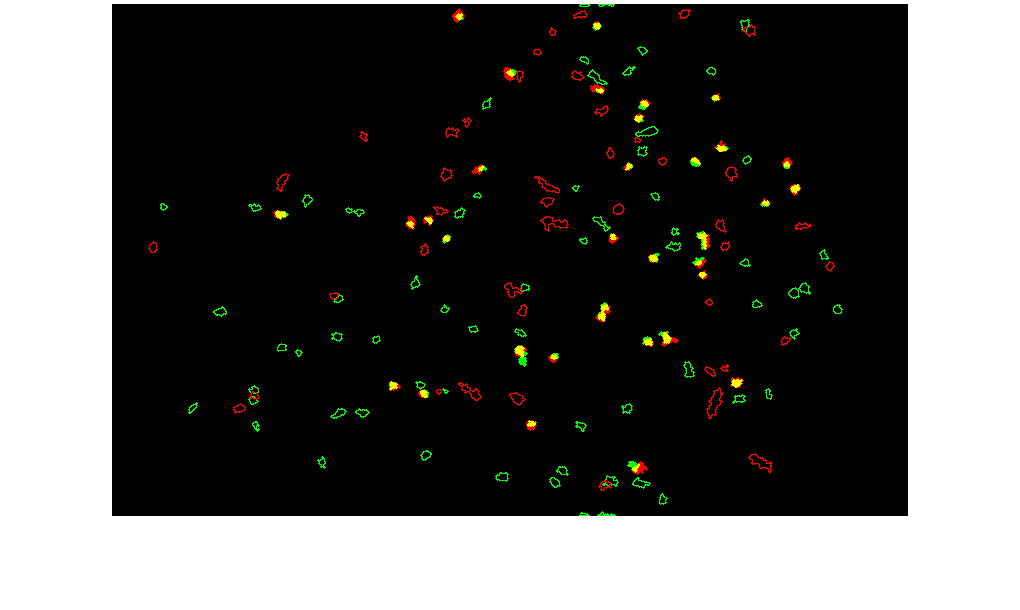

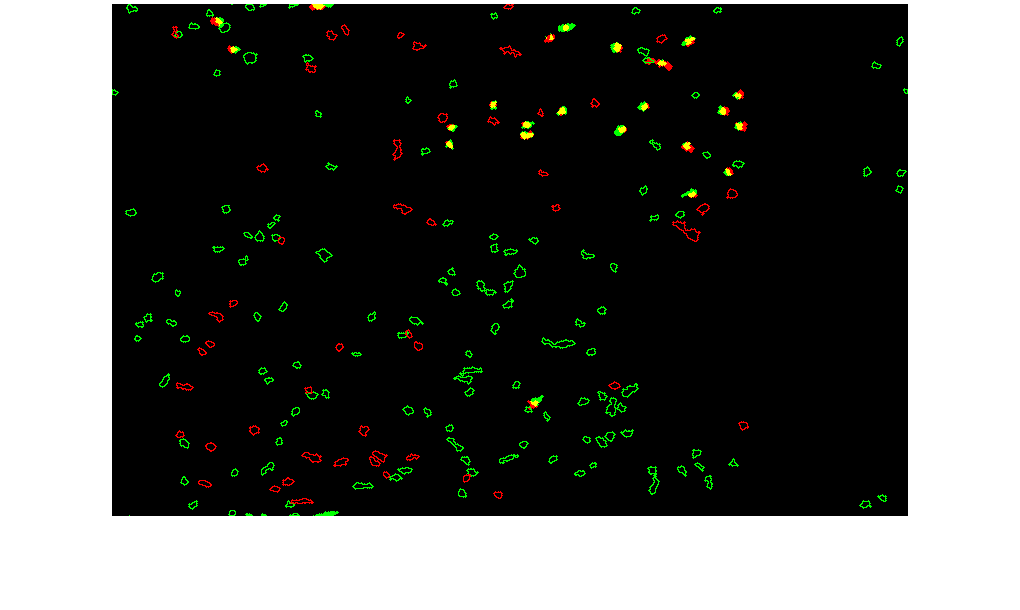

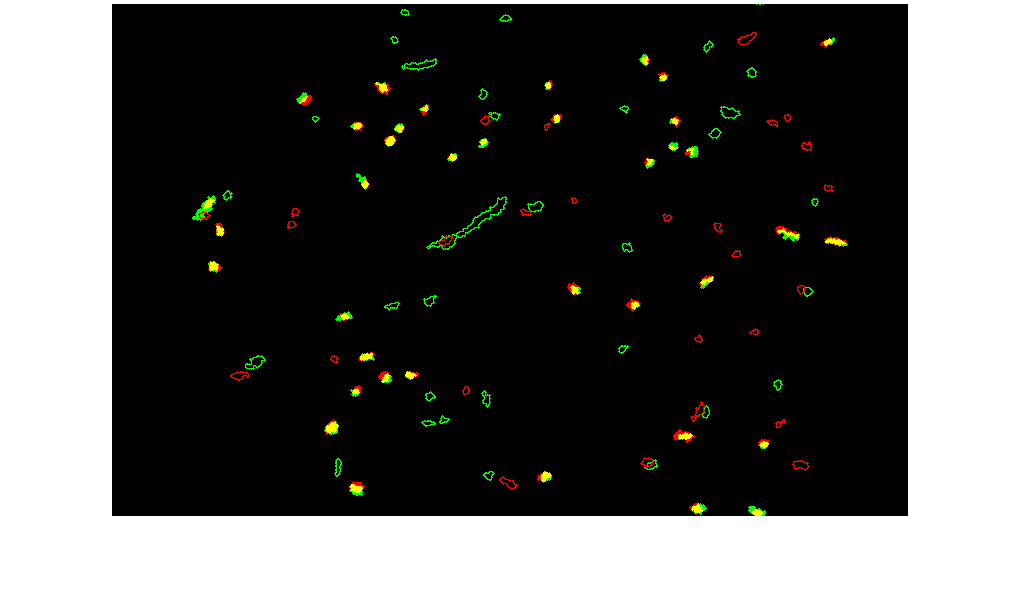

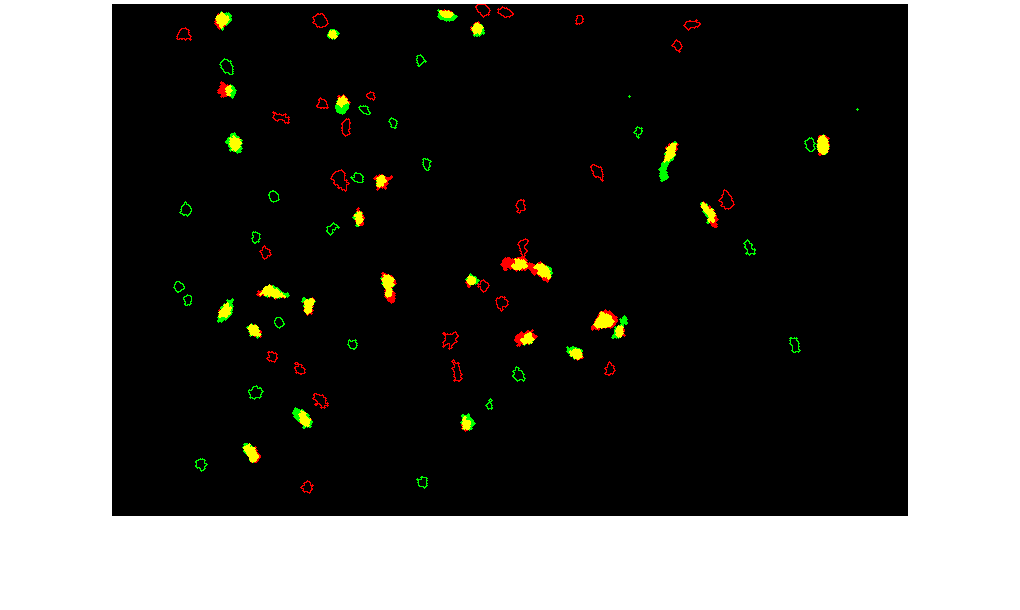

lgn.get_roi_tables(uifs_to_process);

Make sure the imaging fields you wanted are actually in the table....

lgn.roi_stack_uif_list % here are all the imaging fields in the roi table

ans =      1
     2
     3
     9


Lets look at the table

head(lgn.roi_stack) 

ans = 8×22 table
    masterEntry    entryNumber      mouse      uniqImFieldNum    hasRetData    hasTunData    roi_ID_Ret    roi_ID_Tun        kern_ret         kurt_ret        sig_ret            xy_ret       kern_tun    signif_tun    sig_tun      oricurve       oriest       sfcurve       osi    sfPeak    segment_xy_tun    segment_area_tun
    ___________    ___________    _________    ______________    __________    __________    __________    __________    _________________

tail(lgn.roi_stack)

ans = 8×22 table
    masterEntry    entryNumber      mouse      uniqImFieldNum    hasRetData    hasTunData    roi_ID_Ret    roi_ID_Tun        kern_ret         kurt_ret        sig_ret            xy_ret          kern_tun       signif_tun        sig_tun           oricurve            oriest            sfcurve              osi                  sfPeak                     segment_xy_tun               segment_area_tun
    ___________    ___________    _________    ______________    __________    __________    _________

## You can plot a histogram of any proprety 

Check out some of the properties of the rois.

lgn.roi_stack.Properties.VariableNames

ans = 1×22 cell array
  Columns 1 through 4
    {'masterEntry'}    {'entryNumber'}    {'mouse'}    {'uniqImFieldNum'}
  Columns 5 through 8
    {'hasRetData'}    {'hasTunData'}    {'roi_ID_Ret'}    {'roi_ID_Tun'}
  Columns 9 through 13
    {'kern_ret'}    {'kurt_ret'}    {'sig_ret'}    {'xy_ret'}    {'kern_tun'}
  Columns 14 through 18
    {'signif_tun'}    {'sig_tun'}    {'oricurve'}    {'oriest'}    {'sfcurve'}
  Columns 19 through 22
    {'osi'}    {'sfPeak'}    {'segment_xy_tun'}    {'segment_area_tun'}

plot it

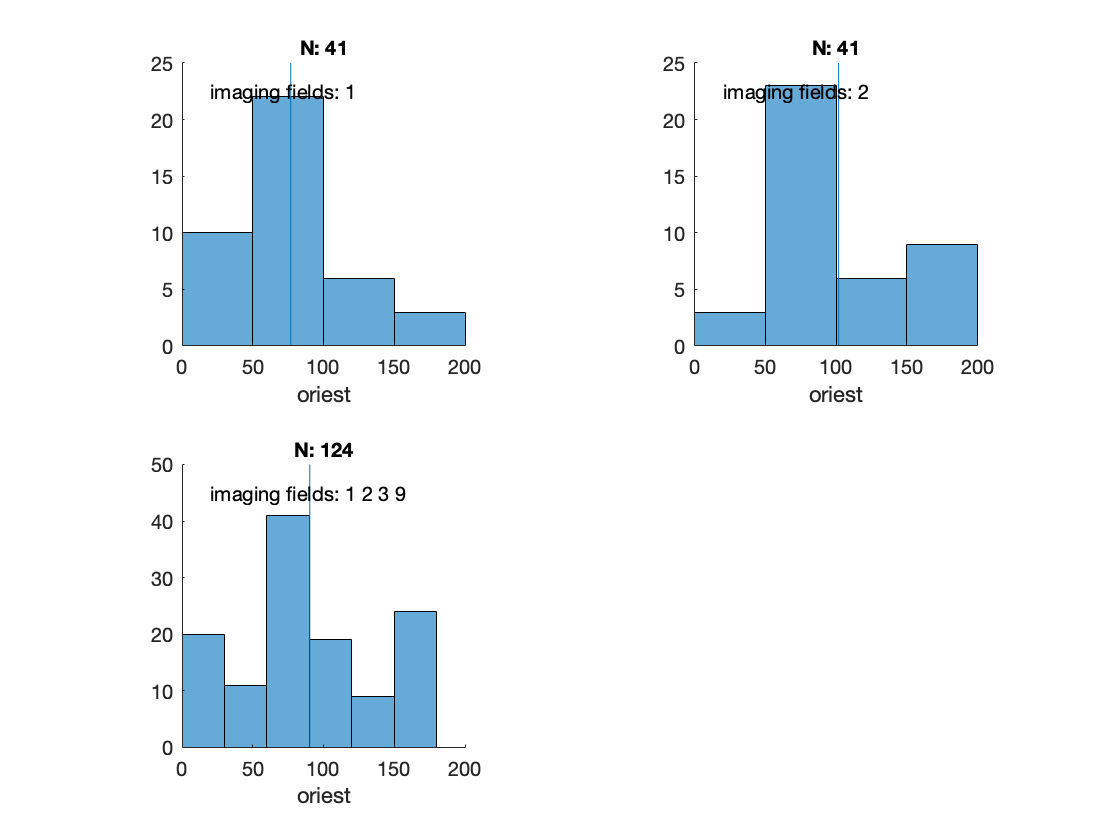

close all
variable_name = 'oriest';
main_requirement = logical(lgn.roi_stack.signif_tun);

uif1_roi_requirments = lgn.roi_stack.uniqImFieldNum == 1 & main_requirement;
tbl_uif1_of_single_rois = lgn.roi_stack(uif1_roi_requirments,:);
lgn.plot_univar_hist(tbl_uif1_of_single_rois, variable_name)

uif2_roi_requirments = lgn.roi_stack.uniqImFieldNum == 2 & main_requirement;
tbl_uif2_of_single_rois = lgn.roi_stack(uif2_roi_requirments,:);
lgn.plot_univar_hist(tbl_uif2_of_single_rois, variable_name)

uifALL_roi_requirments = main_requirement;
tbl_uifALL_of_single_rois = lgn.roi_stack(main_requirement,:);
lgn.plot_univar_hist(tbl_uifALL_of_single_rois, variable_name)

`Note that dLGN boutons innervating mouse V1 have preferred orientations that are biased for cardinal orientations. This is similar to the results of Sun et al 2016.`

# Main Analysis

The primary goal is to determine if LGN boutons with overlapping receptive fields have similar tuning profiles. This would suggest  that neurons/units in the dLGN 'process' image regions with a similar, or biased, set of orientated filters. 

To do test this we take each possible pair of boutons (i,j)  in an imaging field, then compute the overlap between their receptive fields, and also compute the similarity of their tuning profiles. We can define the tuning similarity of bouton pairs as the as the correlation between their joint tuning kernels. The RF overlap of bouton pairs can also be defined as the correlation coefficient between their RF maps

To view these pair-wise distant measures between boutons, load the '*distance' *table. Each row  of the table corresponds to a pair of LGN boutons in some imaging field, and the columns correspond to some property of that bouton pair. We are interested in the receptive field overlap and tuning similarity of boutons pairs.

## How to get the distance Table

This loads the distance table

lgn.get_distance_table(); 

Take a look at it.   

lgn.dist_stack(:,{'uniqImFieldNum',... % the imaging field of the bouton pair
 'pair_roiDistMatIdx',... % the index id of each bouton in the pair
 'dRetKern_corr',... % similarity between the receptive fieldsof pairs
 'dTunKern_corr',... % similarity between the joint tuning kernels of pairs
 'dLogSfEst_lessThanOneOct',... % true if the peak spatial frequency of pairs differs by less than 1 octave
 'dLogSfEst_moreThanOneOct',... % true if the peak spatial frequency of pairs is greater than/equal to 1 octave
 'dOriEst'})

ans = 40×7 table
    uniqImFieldNum    pair_roiDistMatIdx    dRetKern_corr       dTunKern_corr        dLogSfEst_lessThanOneOct    dLogSfEst_moreThanOneOct        dOriEst     
    ______________    __________________    _____________    ____________________    ________________________    ________________________    ________________
          1                 2    1            0.9587755         0.960400505662517               1                           0                15.8193554979177
          1                 3    1            0.4528934         0.558680858407889               1                           0                77.4824974042373
          1                 4    1             0.745438        -0.137264610903937               0                

## Model the relationship between tuning similarity and RF overlap

Now that we have a data table of pairs, plot the relationship between tuning similarity and receptive field overlap. Run once for a single imaging 

clf;

uif_list  = lgn.roi_stack_uif_list(3)

uif_list =      3

dY_name = 'dTunKern_corr'

dY_name = 'dTunKern_corr'

dX_name = 'dRetKern_corr'

dX_name = 'dRetKern_corr'

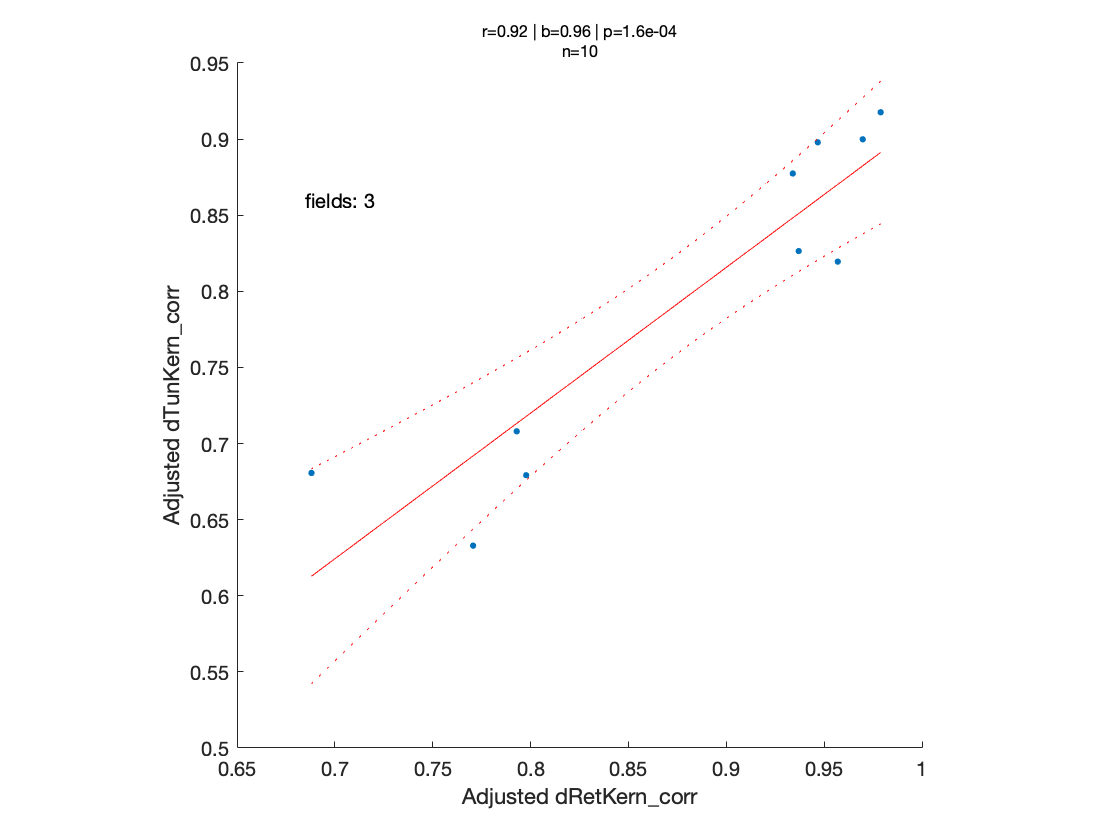

lgn.fit_plot_lm(uif_list, dY_name, dX_name);

and again but this time with all pairs of boutons, accross all imaging fields


clf; 
uif_list   = lgn.roi_stack_uif_list(:)

uif_list =      1
     2
     3
     9


dY_name = 'dTunKern_corr'

dY_name = 'dTunKern_corr'

dX_name = 'dRetKern_corr'

dX_name = 'dRetKern_corr'

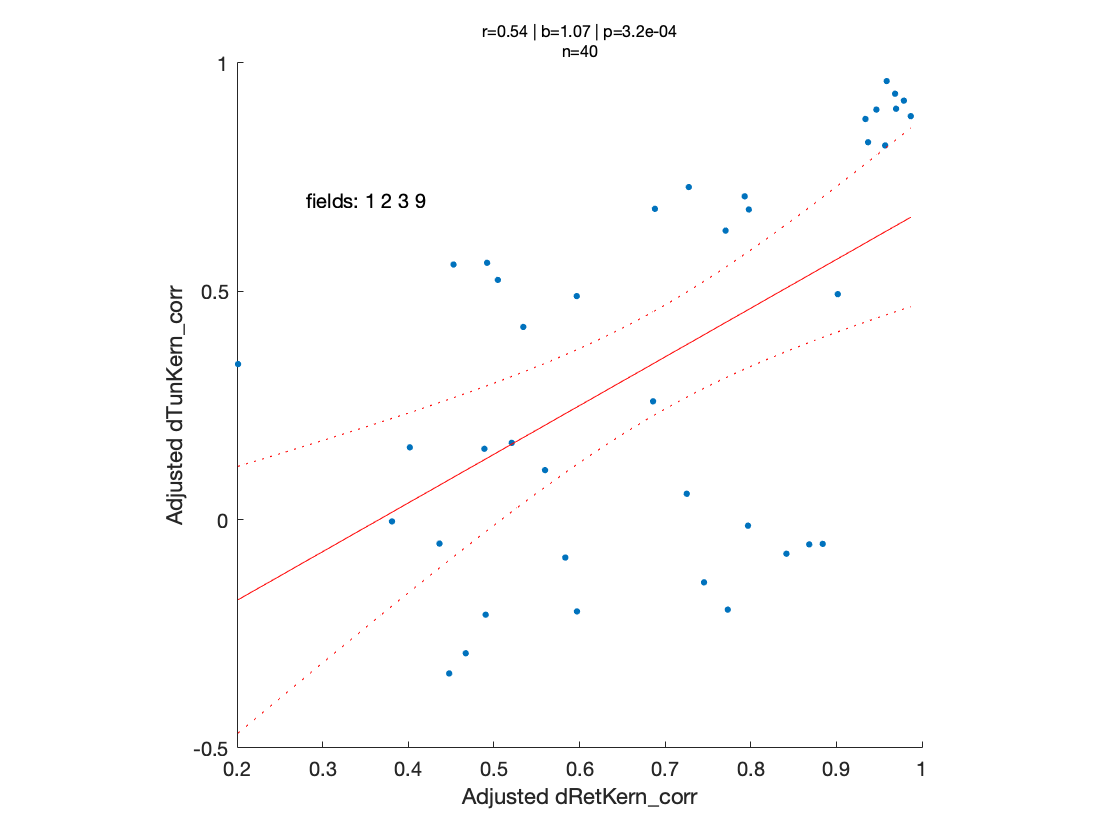

ans =   3×1 Line array:

  Line    (data)
  Line    (fit)
  Line    (95% conf. bounds)

lgn.fit_plot_lm(uif_list, dY_name, dX_name)

## Discussion